clear all
close all
clc

%%% read raw data from camera generated PTW file %%%
[filename pathname] = uigetfile('*.ptw*', 'Choose a picture ptw file');
fid = fopen([pathname filename],'r');

Error using fopen
File identifier must be an integer-valued scalar of type double.

LgthFileMainHeader = 3476;
LgthImHeader = 1016;
%Seek the number pixel in an image:
fseek(fid, 23, 'bof');
NbPixelImage = fread(fid,1,'uint32');
%Seek the total number of image:
fseek(fid, 27, 'bof');
Nbimage = fread(fid,1,'uint32');
%Seek the height of the images
fseek(fid, 377, 'bof');
NbColImage = fread(fid,1,'uint16');
%Seek the width of the images
fseek(fid, 379, 'bof');
NbRowImage = fread(fid,1,'uint16');
%Set the file point on the header of the first image
fseek(fid, 3476, 'bof');
A = zeros(NbRowImage,NbColImage,Nbimage,'uint16');
h = waitbar(0,[filename ' database importation : ' num2str(0) '/' num2str(Nbimage)]);
for i=1:(Nbimage)
waitbar(i/Nbimage,h,[filename ' database importation : ' num2str(i) '/' num2str(Nbimage) ]);
fread(fid,1016);%Jump the image header
B = fread( fid , [NbColImage,NbRowImage] , 'uint16' );
[M,N] = size(B);
A(:,:,i) = uint16( B( 1:NbColImage , 1:NbRowImage )' );  %%% A is x*y*intensity versus time data
end
close(h)
fclose('all');

%%% extract phase %%%
FPS = 225; %frames per second
start_time = 0; %s
end_time = 125; %s
x = 1:1:640; %horizontal location on the ccd camera
peak_location = [];
for i = start_time*FPS+1:1:end_time*FPS
    z = double(A(:,:,i));
    c = zeros(1,640);
    for j = 1:1:640
        c(j) = sum(z(:,j));
    end
    y = normalize(smooth(x,c,80),'range');
    [pks,locs] = findpeaks(y,x,'MinPeakDistance',20,'MinPeakProminence',0.2);
    peak_location(i,:)= locs;
end

Unrecognized function or variable 'A'.

phase = 2*(peak_location(:,2)-294)./(492-294); %294 and 492 are peak locations at zero phase change

%%% talior phase vs time data %%%
load('phase5010_low.mat')
load('s5010.mat') %load 1000 input signal bits
start_point = 1646;
end_point = 14964;
n = end_point-start_point+1;
tvec = 1:1:n;
outp = phase(start_point:end_point);

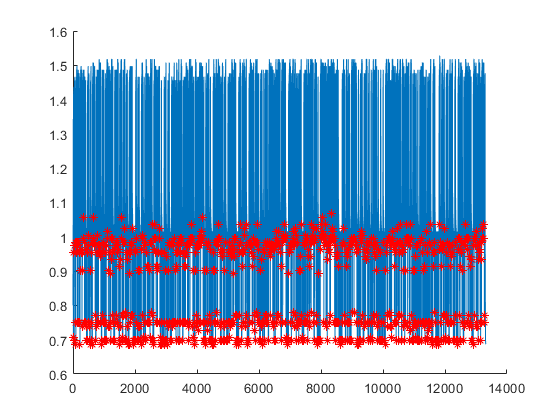

%%% Divide the continuous recorded data to 1000 equal-length individual bits %%%
%%% manually do clasification to get correct answer for clasification problems

TF = islocalmin(outp,'MinSeparation',5,'FlatSelection', 'last','MinProminence',0.05);
N = nnz(TF); 
arr = 1:n;
arrTF = arr(TF); % store minimum point's index in outp
%adjust minimum point position
for i = 1:N
    
    for j = 1:25
        if outp(arrTF(i)+j) > outp(arrTF(i)+j-1)+0.05
            break
        end
    end
    for jj = 1:20 
        if outp(arrTF(i)+j-1-jj) >=  outp(arrTF(i)+j-1-jj+1)
            break
        end
    end
    TF(arrTF(i)) = 0;
    TF(arrTF(i)+j-1-jj+1) = 1;
    arrTF(i) = arrTF(i)+j-1-jj+1;
end
%exam the data, sometimes need to manually adjust some minimum points
figure; hold on;
plot(tvec,outp,tvec(TF),outp(TF),'r*')

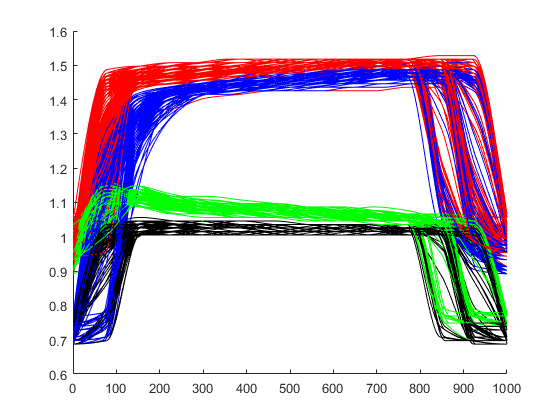


%the frame rate of camera is not perfect stable, 
%we need to interpolation to make each bit euqal-length
%number of weights means the number of points we picked for interpolation
number_of_weights = 1000; 
out_M = zeros(N-1,number_of_weights); % matrix store all the interpolated bits

%There are four types of data 00 01 10 11, as mentioned in the paper
%we did three kinds of classification,
%%1. XOR which classify 00 and 11 to 1, 01 and 10 to 0
%%2. directly classify 00 to 1, 10 to 2, 01 to 3, 11 to 4
%%3. classify four types of data by 4 sperate classification, 
%such as 00 to 1, 01 10 11 to 0, and so on

%type 1 classification
y_xor = arr_XOR(S,1); % arr_XOR is a function written for get correct answer for XOR classification
%type 2 classification
y_4 = zeros(size(y_xor));
%type 3 classification
y_4_00 = zeros(size(y_xor));
y_4_10 = zeros(size(y_xor));
y_4_01 = zeros(size(y_xor));
y_4_11 = zeros(size(y_xor));

%count how many bit are there for each types of signal 
%and record their index in ind00...11
count = zeros(4,1); 
ind00 = zeros(998,1);
ind01 = zeros(998,1);
ind10 = zeros(998,1);
ind11 = zeros(998,1);

f2 = figure; hold on;

%loop all the bits
for i = 1:N-1
    
    %interpolation
    temp = outp(arrTF(i):arrTF(i+1));
    K = size(temp,1);
    svec = 1:K;
    qvec = 1:(K-1)/(number_of_weights-1):K;
    tempq = interp1(svec,temp,qvec,'pchip');
    
    %store interpolated equal-length data
    out_M(i,:) = tempq(:);
    
    %manually classify the data to get correct answer for type 2 and 3
    %also plot folded dynamics plot as in Fig.4b
    if S(i) == 1
        if S(i+1) == 1
            figure(f2);
            plot(tempq,'r')
            y_4(i) = 4;
            y_4_11(i) = 1;
            count(4) = count(4)+1;
            ind11(count(4)) = i;
        elseif S(i+1) == 0
            figure(f2);
            plot(tempq,'g')
            y_4(i) = 2;
            y_4_10(i) = 1;
            count(3) = count(3)+1;
            ind10(count(3)) = i;
        end
    elseif S(i) == 0
        if S(i+1) == 1
            figure(f2);
            plot(tempq,'b')
            y_4(i) = 3;
            y_4_01(i) = 1;
            count(2) = count(2)+1;
            ind01(count(2)) = i;
        elseif S(i+1) == 0
            figure(f2);
            plot(tempq,'k')
            y_4(i) = 1;
            y_4_00(i) = 1;
            count(1) = count(1)+1;
            ind00(count(1)) = i;
        end
    end
end

%%% PCA claculation and plot %%%
%use matlab's PCA function to get scores
[~,score,~,~,explained,~] = pca(out_M);

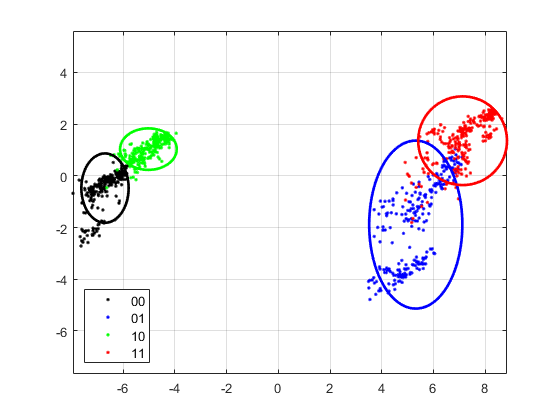


% allocate scores to each types, only use first and second PCs
d1 = ones(2,count(1));
d2 = ones(2,count(2));
d3 = ones(2,count(3));
d4 = ones(2,count(4));
for i = 1:count(1)
    d1(1,i) = score(ind00(i),1);
    d1(2,i) = score(ind00(i),2);
end
for i = 1:count(2)
    d2(1,i) = score(ind01(i),1);
    d2(2,i) = score(ind01(i),2);
end
for i = 1:count(3)
    d3(1,i) = score(ind10(i),1);
    d3(2,i) = score(ind10(i),2);
end
for i = 1:count(4)
    d4(1,i) = score(ind11(i),1);
    d4(2,i) = score(ind11(i),2);
end

% Compute mean and std
mean1 = mean(d1,2);
std1 = std(d1,[],2); 
mean2 = mean(d2,2);
std2 = std(d2,[],2); 
mean3 = mean(d3,2);
std3 = std(d3,[],2); 
mean4 = mean(d4,2);
std4 = std(d4,[],2); 

% Plot data
figure()
plot(d1(1,:),d1(2,:),'k.')
hold on
plot(d2(1,:),d2(2,:),'b.')
hold on
plot(d3(1,:),d3(2,:),'g.')
hold on
plot(d4(1,:),d4(2,:),'r.')
axis equal %this is important so circles appear as circles
grid on
% Plot ellipses, then change their color and other properties
h = plotEllipses(mean1,2*std1); 
%h.FaceColor = [0 0 1 0.3]; %4th value is undocumented: transparency
h.EdgeColor = 'k'; 
h.LineWidth = 2; 
h = plotEllipses(mean2,2*std2); 
%h.FaceColor = [1 0 0 0.3]; %4th value is undocumented: transparency
h.EdgeColor = 'b'; 
h.LineWidth = 2; 
h = plotEllipses(mean3,2*std3); 
%h.FaceColor = [1 0 0 0.3]; %4th value is undocumented: transparency
h.EdgeColor = 'g'; 
h.LineWidth = 2; 
h = plotEllipses(mean4,2*std4); 
%h.FaceColor = [1 0 0 0.3]; %4th value is undocumented: transparency
h.EdgeColor = 'r'; 
h.LineWidth = 2; 

lgd = legend('00','01','10','11','Location','southwest');
lgd.FontSize = 10;

%%% Divide data into training and testing part %%%
%%% Use Ridge regression as linear training layer to get weights %%%
number_of_training = 800;
number_of_testing = N-1-number_of_training

number_of_testing = 198


ytrain_xor = y_xor(1:number_of_training);
ytest_xor = y_xor(number_of_training+1:N-1);

ytrain_4 = y_4(1:number_of_training);
ytest_4 = y_4(number_of_training+1:N-1);

ytrain_4_00 = y_4_00(1:number_of_training);
ytest_4_00 = y_4_00(number_of_training+1:N-1);
ytrain_4_10 = y_4_10(1:number_of_training);
ytest_4_10 = y_4_10(number_of_training+1:N-1);
ytrain_4_01 = y_4_01(1:number_of_training);
ytest_4_01 = y_4_01(number_of_training+1:N-1);
ytrain_4_11 = y_4_11(1:number_of_training);
ytest_4_11 = y_4_11(number_of_training+1:N-1);

out_M_train = out_M(1:number_of_training,:);
out_M_test = out_M(number_of_training+1:N-1,:);

kc = 0.0000001;

w_xor = ridge(ytrain_xor,out_M_train,kc,0);
w_4 = ridge(ytrain_4,out_M_train,kc,0);
w_4_00 = ridge(ytrain_4_00,out_M_train,kc,0);
w_4_10 = ridge(ytrain_4_10,out_M_train,kc,0);
w_4_01 = ridge(ytrain_4_01,out_M_train,kc,0);
w_4_11 = ridge(ytrain_4_11,out_M_train,kc,0);


%%%training%%%

%get training output
yo_xor_train = w_xor(1) + out_M_train*w_xor(2:end);

yo_4_train = w_4(1) + out_M_train*w_4(2:end);

yo_4_00_train = w_4_00(1) + out_M_train*w_4_00(2:end);
yo_4_10_train = w_4_10(1) + out_M_train*w_4_10(2:end);
yo_4_01_train = w_4_01(1) + out_M_train*w_4_01(2:end);
yo_4_11_train = w_4_11(1) + out_M_train*w_4_11(2:end);

%truth rate
th = 0.5;

% correct count
ct_xor_train = 0;
ct_4_train = 0;
ct_4_B_train = 0;

%build this table to record all kinds of result, easier examing the data
train_table = zeros(number_of_training,19);

%truth table
train_4_M = [0 100 110 101 111; 100 0 0 0 0; 110 0 0 0 0; 101 0 0 0 0; 111 0 0 0 0]

train_4_M =      0   100   110   101   111
   100     0     0     0     0
   110     0     0     0     0
   101     0     0     0     0
   111     0     0     0     0


train_4_M_B = [0 100 110 101 111; 100 0 0 0 0; 110 0 0 0 0; 101 0 0 0 0; 111 0 0 0 0]

train_4_M_B =      0   100   110   101   111
   100     0     0     0     0
   110     0     0     0     0
   101     0     0     0     0
   111     0     0     0     0




%Type 1, xor
for i=1:number_of_training
    
    train_table(i,1) = i; %   1   index
                          %   2   empty
    train_table(i,3) = ytrain_xor(i);  %   3   XOR true value
    
    train_table(i,4) = yo_xor_train(i); %   4   XOR raw result
    
    if train_table(i,4)>th
        train_table(i,5) = 1; %   5   XOR result 0/1
    end
   
    train_table(i,7) = ytrain_4(i); %   7   four value train true value
    
    if train_table(i,3)~=train_table(i,5)
        train_table(i,6) = 1; %   6   XOR pass 0/fail 1
        ct_xor_train = ct_xor_train+1;
        train_table(i,:) %print out mis-classified bits
    end
end

ans =    25.0000         0         0    0.5477    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =    35.0000         0    1.0000    0.4179         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =    72.0000         0    1.0000    0.3846         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   105.0000         0    1.0000    0.0978         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   117.0000         0         0    0.8185    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   131.0000         0    1.0000    0.4847         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   150.0000         0         0    0.6907    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   151.0000         0         0    0.5060    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   190.0000         0    1.0000    0.3606         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   191.0000         0         0    0.5453    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   198.0000         0         0    0.5538    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   202.0000         0    1.0000    0.4874         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   206.0000         0         0    0.5326    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   246.0000         0    1.0000    0.4975         0    1.0000    2.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   271.0000         0    1.0000    0.4956         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   293.0000         0    1.0000    0.4740         0    1.0000    2.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   313.0000         0         0    0.6131    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   325.0000         0         0    0.5919    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   349.0000         0    1.0000    0.4192         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   357.0000         0         0    0.5662    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   390.0000         0    1.0000    0.2881         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   404.0000         0    1.0000    0.0384         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   407.0000         0    1.0000    0.3717         0    1.0000    2.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   416.0000         0         0    0.5742    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   431.0000         0         0    0.8213    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   438.0000         0         0    0.5239    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   445.0000         0    1.0000    0.4229         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   471.0000         0    1.0000    0.4048         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   502.0000         0         0    0.6917    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   523.0000         0    1.0000    0.3715         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   538.0000         0         0    0.6262    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   578.0000         0    1.0000    0.3597         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   595.0000         0    1.0000    0.3669         0    1.0000    2.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   600.0000         0    1.0000    0.1706         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   623.0000         0    1.0000    0.4310         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   627.0000         0         0    0.8654    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   638.0000         0    1.0000    0.3929         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   678.0000         0    1.0000    0.3537         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   682.0000         0    1.0000    0.0078         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   683.0000         0         0    0.5478    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   730.0000         0    1.0000    0.4877         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   760.0000         0         0    0.5498    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   767.0000         0    1.0000    0.1190         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   770.0000         0    1.0000    0.3257         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   792.0000         0    1.0000    0.4757         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   793.0000         0         0    0.6224    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans =   800.0000         0         0    0.5603    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0




%Type 2, 'four value'
for i=1:number_of_training
    
    train_table(i,7) = ytrain_4(i); %   7   four value train true value
    
    train_table(i,8) = yo_4_train(i); %   8   four value train raw result 
    
    if train_table(i,8) <= 1.5
        train_table(i,9) = 1; %   9   four value result 1/2/3/4
    elseif train_table(i,8) <= 2.5
        train_table(i,9) = 2;
    elseif train_table(i,8) <= 3.5
        train_table(i,9) = 3;
    else
        train_table(i,9) = 4;
    end
    
    train_4_M(train_table(i,7)+1,train_table(i,9)+1) = train_4_M(train_table(i,7)+1,train_table(i,9)+1)+1;
    
    if train_table(i,7) ~= train_table(i,9)
        train_table(i,:) %print out mis-classified bits
        ct_4_train = ct_4_train+1;
        %plot(1:number_of_weights,out_M_train(i,:))
    end
end

ans =     1.0000         0         0    0.0013         0         0    4.0000    2.9215    3.0000         0         0         0         0         0         0         0         0         0         0


ans = 1×19
   51.0000         0    1.0000    0.6135    1.0000         0    3.0000    3.8306    4.0000         0         0         0         0         0         0         0         0         0         0



train_4_M

train_4_M = 5×5
     0   100   110   101   111
   100   210     0     0     0
   110     0   195     0     0
   101     0     0   194     1
   111     0     0     1   199



%Type 3, 'binary test'
for i=1:number_of_training
    
    train_table(i,10) = nan;            %   10   empty
    train_table(i,11) = ytrain_4_00(i); %   11   Binary train true value 00
    train_table(i,12) = ytrain_4_10(i); %   12   Binary train true value 10
    train_table(i,13) = ytrain_4_01(i); %   13   Binary train true value 01
    train_table(i,14) = ytrain_4_11(i); %   14   Binary train true value 11
    
    train_table(i,15) = nan;              %   15   empty
    train_table(i,16) = yo_4_00_train(i); %   16   Binary train raw result 00
    train_table(i,17) = yo_4_10_train(i); %   17   Binary train raw result 10
    train_table(i,18) = yo_4_01_train(i); %   18   Binary train raw result 01
    train_table(i,19) = yo_4_11_train(i); %   19   Binary train raw result 11
    
    
    [iii,true_index]=max(train_table(i,11:14));
    [iiii,out_index]=max(train_table(i,16:19));
    
    train_4_M_B(true_index+1,out_index+1) = train_4_M_B(true_index+1,out_index+1)+1;
    
    if true_index ~= out_index
        train_table(i,:) %print out mis-classified bits
        ct_4_B_train = ct_4_B_train+1;
        %plot(1:number_of_weights,out_M_train(i,:))
    end
end

ans = 1×19
    1.0000         0         0    0.0013         0         0    4.0000    2.9215    3.0000       NaN         0         0         0    1.0000       NaN    0.5086   -0.4485    0.4498    0.4901


ans = 1×19
   51.0000         0    1.0000    0.6135    1.0000         0    3.0000    3.8306    4.0000       NaN         0         0    1.0000         0       NaN   -0.2719    0.3716    0.2419    0.6584


ans = 1×19
  105.0000         0    1.0000    0.0978         0    1.0000    3.0000    3.2009    3.0000       NaN         0         0    1.0000         0       NaN    0.3639   -0.3902    0.4880    0.5384


ans = 1×19
  404.0000         0    1.0000    0.0384         0    1.0000    3.0000    3.1718    3.0000       NaN         0         0    1.0000         0       NaN    0.3933   -0.3902    0.4285    0.5683


ans = 1×19
  682.0000         0    1.0000    0.0078         0    1.0000    3.0000    3.2092    3.0000       NaN         0         0    1.0000         0       NaN    0.4037   -0.4280    0.4358    0.5885


ans = 1×19
  767.0000         0    1.0000    0.1190         0    1.0000    3.0000    3.1840    3.0000       NaN         0         0    1.0000         0       NaN    0.3589   -0.3795    0.4985    0.5221



train_4_M_B

train_4_M_B = 5×5
     0   100   110   101   111
   100   210     0     0     0
   110     0   195     0     0
   101     0     0   190     5
   111     1     0     0   199





%get error rate
train_err_xor = ct_xor_train/number_of_training

train_err_xor = 0.0588

train_err_4 = ct_4_train/number_of_training

train_err_4 = 0.0025

train_err_B = ct_4_B_train/number_of_training

train_err_B = 0.0075

%%%testing%%%

%get testing output
yo_xor_test = w_xor(1) + out_M_test*w_xor(2:end);

yo_4_test = w_4(1) + out_M_test*w_4(2:end);

yo_4_00_test = w_4_00(1) + out_M_test*w_4_00(2:end);
yo_4_10_test = w_4_10(1) + out_M_test*w_4_10(2:end);
yo_4_01_test = w_4_01(1) + out_M_test*w_4_01(2:end);
yo_4_11_test = w_4_11(1) + out_M_test*w_4_11(2:end);

%truth rate
th = 0.5;

% correct count
ct_xor_test = 0;
ct_4_test = 0;
ct_4_B_test = 0;

%build this table to record all kinds of result, easier examing the data
test_table = zeros(number_of_testing,19);

%truth table
test_4_M = [0 100 110 101 111; 100 0 0 0 0; 110 0 0 0 0; 101 0 0 0 0; 111 0 0 0 0];
test_4_M_B = [0 100 110 101 111; 100 0 0 0 0; 110 0 0 0 0; 101 0 0 0 0; 111 0 0 0 0];


%Type 1, XOR
for i=1:number_of_testing
    test_table(i,1) = i+number_of_training; %   1   index
                          %   2   empty
    test_table(i,3) = ytest_xor(i);  %   3   XOR true value
    
    test_table(i,4) = yo_xor_test(i); %   4   XOR raw result
    
    if test_table(i,4)>th
        test_table(i,5) = 1; %   5   XOR result 0/1
    end
   
    test_table(i,7) = ytest_4(i); %   7   four value test true value
    
    if test_table(i,3)~=test_table(i,5)
        test_table(i,6) = 1; %   6   xor pass 0/fail 1
        ct_xor_test = ct_xor_test+1;
        test_table(i,:) %print out mis-classified bits
    end
end

ans = 1×19
  807.0000         0    1.0000    0.3354         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans = 1×19
  808.0000         0         0    0.5142    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans = 1×19
  819.0000         0         0    0.5352    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans = 1×19
  867.0000         0         0    1.3482    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans = 1×19
  868.0000         0    1.0000   -0.7935         0    1.0000    2.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans = 1×19
  869.0000         0         0    0.5343    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans = 1×19
  877.0000         0    1.0000   -0.0957         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans = 1×19
  891.0000         0    1.0000    0.3369         0    1.0000    2.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans = 1×19
  898.0000         0         0    0.6967    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans = 1×19
  900.0000         0         0    0.5786    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans = 1×19
  907.0000         0    1.0000    0.4235         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans = 1×19
  918.0000         0    1.0000    0.1417         0    1.0000    3.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans = 1×19
  938.0000         0         0    0.6206    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


ans = 1×19
  941.0000         0         0    0.5777    1.0000    1.0000    4.0000         0         0         0         0         0         0         0         0         0         0         0         0


    
%Type 2, four value
for i=1:number_of_testing
    
    test_table(i,8) = yo_4_test(i); %   8   raw result of four value test
    
    if test_table(i,8) <= 1.5
        test_table(i,9) = 1; %   9   four value test result 1/2/3/4
    elseif test_table(i,8) <= 2.5
        test_table(i,9) = 2;
    elseif test_table(i,8) <= 3.5
        test_table(i,9) = 3;
    else
        test_table(i,9) = 4;
    end
    
    test_4_M(test_table(i,7)+1,test_table(i,9)+1) = test_4_M(test_table(i,7)+1,test_table(i,9)+1)+1;
    
    if test_table(i,7) ~= test_table(i,9)
        test_table(i,:) %print out mis-classified bits
        ct_4_test = ct_4_test+1;
        %plot(1:number_of_weights,out_M_test(i,:))
    end
end

ans = 1×19
  869.0000         0         0    0.5343    1.0000    1.0000    1.0000    1.7009    2.0000         0         0         0         0         0         0         0         0         0         0


ans = 1×19
  898.0000         0         0    0.6967    1.0000    1.0000    1.0000    1.7028    2.0000         0         0         0         0         0         0         0         0         0         0


ans = 1×19
  983.0000         0    1.0000    3.6477    1.0000         0    3.0000    0.6237    1.0000         0         0         0         0         0         0         0         0         0         0



test_4_M

test_4_M = 5×5
     0   100   110   101   111
   100    57     2     0     0
   110     0    48     0     0
   101     1     0    46     0
   111     0     0     0    44



%Type 3, binary test
for i=1:number_of_testing
    
    test_table(i,10) = nan;            %   10   empty
    test_table(i,11) = ytest_4_00(i); %   11   Binary test true value 00
    test_table(i,12) = ytest_4_10(i); %   12   Binary test true value 10
    test_table(i,13) = ytest_4_01(i); %   13   Binary test true value 01
    test_table(i,14) = ytest_4_11(i); %   14   Binary test true value 11
    
    test_table(i,15) = nan;              %   15   empty
    test_table(i,16) = yo_4_00_test(i); %   16   Binary test raw result 00
    test_table(i,17) = yo_4_10_test(i); %   17   Binary test raw result 10
    test_table(i,18) = yo_4_01_test(i); %   18   Binary test raw result 01
    test_table(i,19) = yo_4_11_test(i); %   19   Binary test raw result 11
    
    
    [asdfasd,true_index]=max(test_table(i,11:14));
    [adfiluh,out_index]=max(test_table(i,16:19));
    
    test_4_M_B(true_index+1,out_index+1) = test_4_M_B(true_index+1,out_index+1)+1;
    
    if true_index ~= out_index
        test_table(i,:) %print out mis-classified bits
        ct_4_B_test = ct_4_B_test+1;
        %plot(1:number_of_weights,out_M_train(i,:))
    end
end

ans = 1×19
  867.0000         0         0    1.3482    1.0000    1.0000    4.0000    3.7969    4.0000       NaN         0         0         0    1.0000       NaN   -0.5642    0.5473    0.8009    0.2159


ans = 1×19
  868.0000         0    1.0000   -0.7935         0    1.0000    2.0000    2.1609    2.0000       NaN         0    1.0000         0         0       NaN    0.8447    0.0984   -0.8920    0.9488


ans = 1×19
  869.0000         0         0    0.5343    1.0000    1.0000    1.0000    1.7009    2.0000       NaN    1.0000         0         0         0       NaN    0.3447    0.7308   -0.1964    0.1210


ans = 1×19
  877.0000         0    1.0000   -0.0957         0    1.0000    3.0000    3.2027    3.0000       NaN         0         0    1.0000         0       NaN    0.4460   -0.4450    0.3493    0.6497


ans = 1×19
  898.0000         0         0    0.6967    1.0000    1.0000    1.0000    1.7028    2.0000       NaN    1.0000         0         0         0       NaN    0.2686    0.7946   -0.0978    0.0347


ans = 1×19
  918.0000         0    1.0000    0.1417         0    1.0000    3.0000    3.1753    3.0000       NaN         0         0    1.0000         0       NaN    0.3371   -0.3284    0.4700    0.5212



test_4_M_B

test_4_M_B = 5×5
     0   100   110   101   111
   100    57     2     0     0
   110     0    47     0     1
   101     0     0    45     2
   111     0     0     1    43




%error rate
test_err_xor = ct_xor_test/number_of_testing

test_err_xor = 0.0707

test_err_4 = ct_4_test/number_of_testing

test_err_4 = 0.0152

test_err_B = ct_4_B_test/number_of_testing

test_err_B = 0.0303